# Getting started

## Basics

Gramm is a Matlab toolbox which allows the quick creation of complex, publication-quality figures in Matlab. One of the main design philosophies is to allow users to make plots by specifying the desired end result. This *declarative *approach is quite different from what you might be used to: specifying the steps, in an *imperative* way, to assemble a plot or visualisation. If you haven't come across this particular set of ideas yet, it might seem a bit strange. But you will soon come to appreciate how powerful and versatile it can be for exploring data and quickly changing how things are presented.

The Matlab implementation of `gramm` is inspired by the [ggplot2](https://ggplot2.tidyverse.org) library for R by Hadley Wickham. A similar library called [Seaborn](https://seaborn.pydata.org) also exists for Python. For an  introduction to the general ideas, have a look at the paper ["A layered grammar of graphics (pdf)"](http://vita.had.co.nz/papers/layered-grammar.pdf) If you are really keen, you can also check out Leland Wilkinson's original book ["The Grammar of Graphics"](https://www.cs.uic.edu/~wilkinson/TheGrammarOfGraphics/GOG.html) that laid the foundation for much of this work.

This live script will demonstrate the basic use of gramm, if you want to see more specific and advanced live scripts, use the links below :

- [Grouped data](matlab:open('./Groups.mlx')) – An example to further explore grouped data that includes visualizations that could accompany an ANOVA.

- [XY data](matlab:open('./XY.mlx')) – An example to further explore X/Y  data, with regressions/fits as well as grouped 2D data

- [Time series](matlab:open('./TimeSeries.mlx')) – An example that showcases the use of gramm to explore repeated time series data

- [Further examples](matlab:open('./examples.mlx')) – Many examples that demonstrate gramm's more advanced capabilities and customizations

## Getting to grips with gramm

### Install

Gramm is easy to install from within MATLAB : Open the Add-ons explorer, search for "gramm" and click Add !

### A first plot

To start out, let's just build a simple scatter plot - but the gramm way. 

We start by loading the `carbig `sample dataset, containing data about new car models between 1970 and 1980.

load example_data;
cars

cars = 406×11 table
                  Model                    Origin      MPG    Cylinders    Displacement    Horsepower    Weight    Acceleration    Model_Year    Origin_Region    Manufacturer 
    _________________________________    __________    ___    _________    ____________    __________    ______    ____________    __________    _____________    _____________

    {'chevroletchevellemalibu'      }    {'USA'   }     18        8            307            130         3504           12            70         {'USA'   }      {'chevrolet'}
    {'buickskylark320'              }    {'USA'   }     15        8          

The data are organised in a way that's  common: we have a table where columns are attributes of the cars (region of origin, cylinders, fuel economy, horsepower...) and each line is a new car model.

One of the main ideas of the *grammar of graphics *is that every plot or visualisation is made up of many different elements that can be combined. The basic elements in this scheme are (1) *data*, (2) *aesthetics*, (3) *geometry *and (4)* statistics*. The *data* refer the numbers/information you want to display. The *aesthetics* are the properties of the graph that you want to map these data to: this could be the x/y position of a point or line segment, the colour, line thickness, and so on. The *geometry* indicates whether you want to use points, lines, etc. And finally, *statistics *corresponds to statistical visualizations/summaries such as error bars, fits, etc.

So let's apply these ideas here:

**a. We create a **`gramm`** object and decide on how we want to map *****data***** to *****aeshetics***. `gramm` is designed in an object-oriented way, so the next few lines might look odd - but the pattern will become familiar very quickly:

g=gramm('x',cars.Model_Year,'y',cars.MPG);

This means: create a `gramm` object which will be assiged to the variable `g`. The `cars.Model_Year`,  column of data will be mapped to the `x`-axis, the fuel economy in miles per gallon (`cars.MPG`) to the `y`-axis.

When you execute this line of code, nothing appears to happen, but if you inspect the workspace, the variable `g` has been created.

**b. Now we add the *****geometry *****we would like to display** by calling the method `geom_point()` on the object `g` since we want to create a scatter plot, which consists of...points.

g.geom_point();

A note here: `g.geom_point()` is equivalent to `geom_point(g)`,  but the dot notation makes it much more explicit that `geom_point()` is called on the object `g`. It's also more readable.

**c. As a final step, we actually need to also explicity call for the figure to be created and drawn.** For this we call `draw()` on the object `g`. This may seem like a drag, but actually it's very useful because it will allow us to stack up calls and make more complicated figures later...

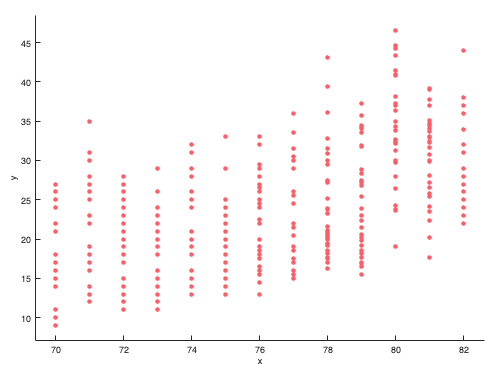

figure
g.draw();

The plot we just produced shows that fuel economy increases with year of production but is not that informative since all vehicles are mixed together. Moreover we had to write three lines to get a figure that MATLAB could do in one line using `plot()! `Now we want to display more information in our figure, and this is where the *grammar of graphics* approach will shine.

### Adding layers of complexity

#### Adding a color aesthetic

Let's say that we want to compare the progression of fuel economy depending on the number of cylinders in the cars. We just need to map the *data* `cars.Cylinders`  to the `color` *aesthetic* to get points colored depending of the number of cylinders of the car.

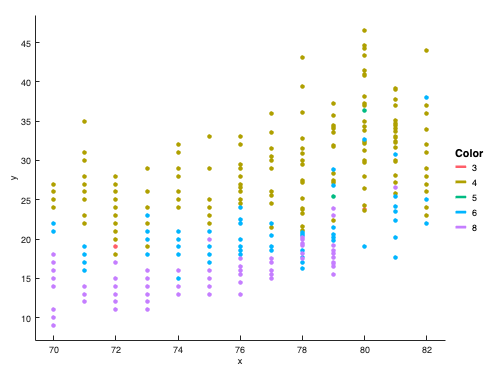

figure
g=gramm('x',cars.Model_Year,'y',cars.MPG,'color',cars.Cylinders); %Added a color aesthetic
g.geom_point();
g.draw();

Notice how `gramm` automatically added the color legend on the right of the plot. This plot is so far equivalent to what could be generated with MATLAB's gscatter.

#### Adding statistical visualizations

Now it seems that cars with less cylinders are ahead in terms of fuel economy, but the discrete year data and superimposed points make it difficult to see those tendencies. We will solve that with two changes :

- We will add linear regressions lines in the plot with the `stats_glm() `method. This is a *statistics *layer

- We will tweak the display of points so that different cylinder counts are slightly shifted along the x-axis

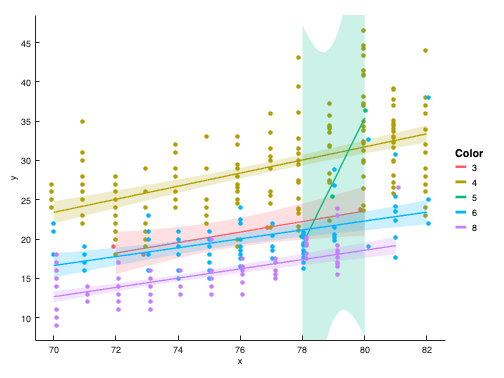

figure
g=gramm('x',cars.Model_Year,'y',cars.MPG,'color',cars.Cylinders);
g.stat_glm(); %Add linear regression lines
g.geom_point("dodge",0.4); %shift groups along the x-axis with the "dodge" argument
g.draw();

With this visualization we see that cars with three and five cylinders are quite rare and clutter our display, let's remove them.

#### Select a subset of data to plot

With gramm it's easy to plot only a subset of the data without having to apply a selection do each variable. This is done with the `'subset'` option when creating the gramm objet, which receives a logical array similar to what you would use for logical indexing.

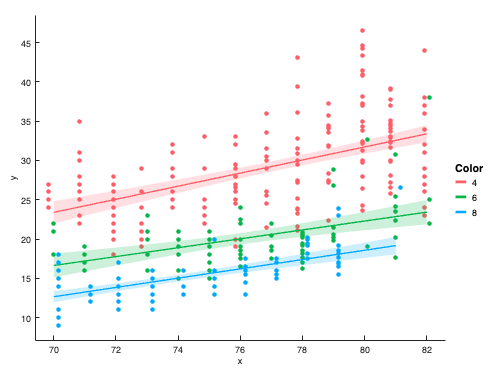

figure
g=gramm('x',cars.Model_Year,'y',cars.MPG,'color',cars.Cylinders, ...
    'subset',cars.Cylinders~=3 & cars.Cylinders~=5); %Select cars that are not 3 or 5 cylinders;
g.stat_glm();
g.geom_point("dodge",0.5); 
g.draw();

Now we are getting somewhere, and the figure is already quite complex with a minimal amount of code. In terms of our exploration of this dataset however, one could argue that this representation might be distorted because different countries favor different amount of cylinders and could have different fuel economy objectives. Let's try to take this in account.

#### Using a variable to create subplots

We could map the region of origin to another *aesthetic* like marker shape or point size, but these are not always easy to read. Here it's probably best to create subplots for each region. This is best done in `gramm` by calling the `facet_grid()` method which receives as arguments the variables to map to subplot rows and to subplot columns.

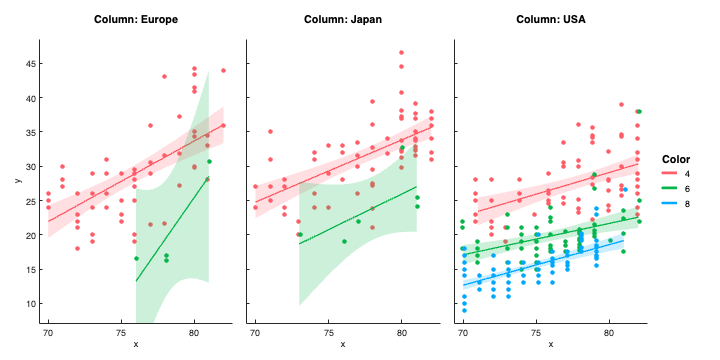

figure('Position',[100 100 800 400]); %We also make the figure a bit wider
g=gramm('x',cars.Model_Year,'y',cars.MPG,'color',cars.Cylinders, ...
    'subset',cars.Cylinders~=3 & cars.Cylinders~=5);
g.facet_grid([],cars.Origin_Region); %Here we want region of origin to determine subplot columns so the first argument (rows) is left empty
g.stat_glm();
g.geom_point("dodge",0.4); 
g.draw();

Notice how all subplots share the same scale which allows easy comparison between subplots. 

#### Final plot : adding a title, fixing legends and exporting

The only thing missing from our figure are proper legends and a title (notice that for now the axes are called x and y, cylinders Color and regions Column). So as a final tweak we provide `gramm` with the necessary information. We will also use the export() method to create a high-resolution file.

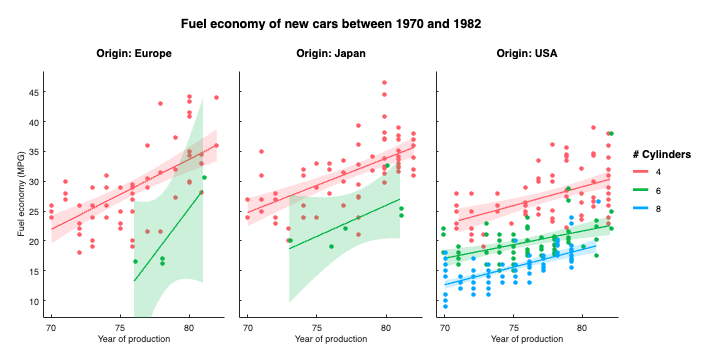

figure('Position',[100 100 800 400]); 
g=gramm('x',cars.Model_Year,'y',cars.MPG,'color',cars.Cylinders,...
    'subset',cars.Cylinders~=3 & cars.Cylinders~=5);
g.facet_grid([],cars.Origin_Region);
g.stat_glm();
g.geom_point("dodge",0.5); 
g.set_names('column','Origin', 'x','Year of production', ... %With set_names() we simply indicate how each aesthetic should be called
    'y','Fuel economy (MPG)','color','# Cylinders');
g.set_title('Fuel economy of new cars between 1970 and 1982'); % With set_title() we provide a big title to the figure
g.draw();

%Export
g.export('export_path','./gramm/html/','file_name','example_export','file_type','png');

## To conclude

With `gramm` we have created a complex figure with only seven lines of code, each of those lines being quite explicit and easy to understand. We also see that changing how the figure is organized would be very easy.  We could swap subplot columns for cylinders and colors for region of origin to better see the worse fuel economy for US cars for similar cylinder counts. Comparatively, creating such a plot with base MATLAB plotting functions would likely require two for loops, three times as many lines of code and would require much rewriting to implement changes.

With this example we only scratched the surface of what is possible with `gramm`, as there are many more geometries and statistical visualizations available, as well as other types of data that can be plotted (categorical data, time series, 3D data). Moreover `gramm` offers many ways to tweak its graphics with built-in options as well as through direct access to the graphical elements *a posteriori*. These possibilities are detailed in other live scripts and in the examples file.